# Diseño filtros FIR

***Método de Parks-McClellan***

% Rizado de la banda de paso en dB
Rp = 0.05;
rp = 10^(Rp/20) - 1; 
% Atenuación de la banda eliminada en dB
Att = 80;
att = 10^(-Att/20);
% Frecuencia de corte del filtro (caida a -3 dB)
fc = 0.15;
% Banda de Transición
Df = 0.1;


## Número óptimo de coeficientes

*El número mínimo de coeficientes se obtienen a partir de la fórmula del artículo de Parks-McClellan:*


$$N_{min} = \frac{-10\cdot log_{10}(r_p\cdot att) - 13}{14.6\cdot \Delta_f} + 1$$


% Mínimo número de coeficientes necesarios
Nmin = (-10*log10(rp*att)-13)/(14.6*Df) + 1

Nmin = 34.8260

## Aplicación del diseño

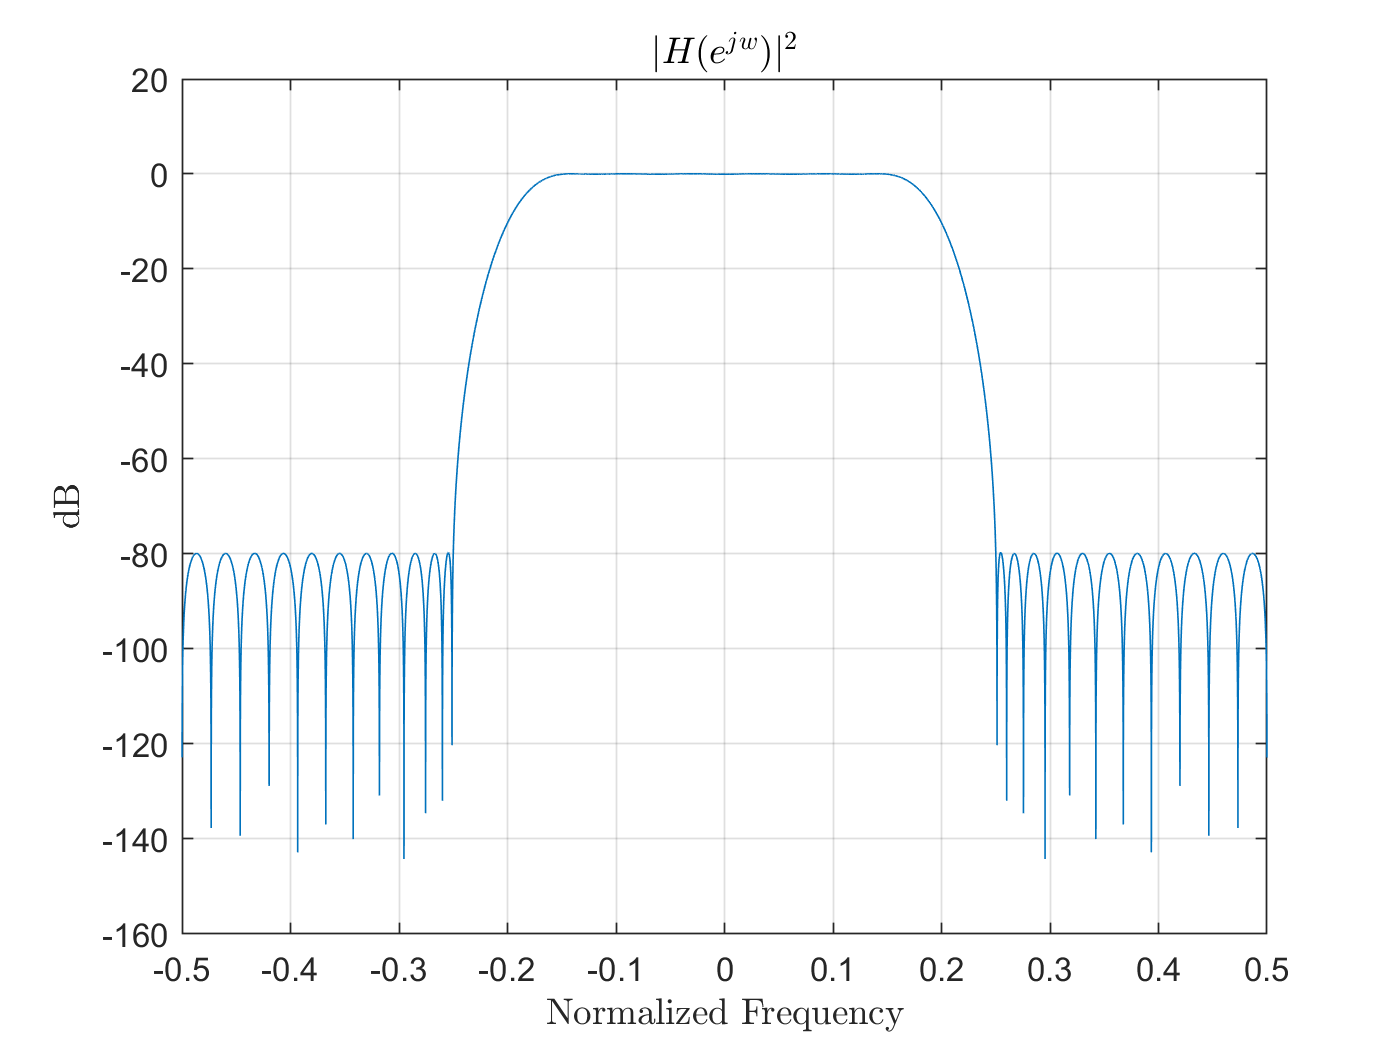

% Máscara de amplitud
amp = [1 1 0 0];
% Eje de frecuencias
freq = [0 fc fc+Df 0.5];
% Diseño del filtro 
h = firpm(ceil(Nmin),freq*2,amp,[att/rp, 1]); % L frecuencia se multiplica por 2 porque hay que introducirlo respecto a pi
% Cálculo de la respuesta en frecuencia del filtro
H = fftshift(fft(h,2^14));
% Visualización gráfica de la respuesta en módulo
f1 = figure;
a1 = axes;
plot(a1,linspace(-0.5,0.5,length(H)),20*log10(abs(H)))
xlabel(a1,'Normalized Frequency','Interpreter',"latex")
ylabel(a1,'dB','Interpreter',"latex")
title(a1,'$|H(e^{jw})|^2$',"Interpreter",'latex')
grid(a1,'on')

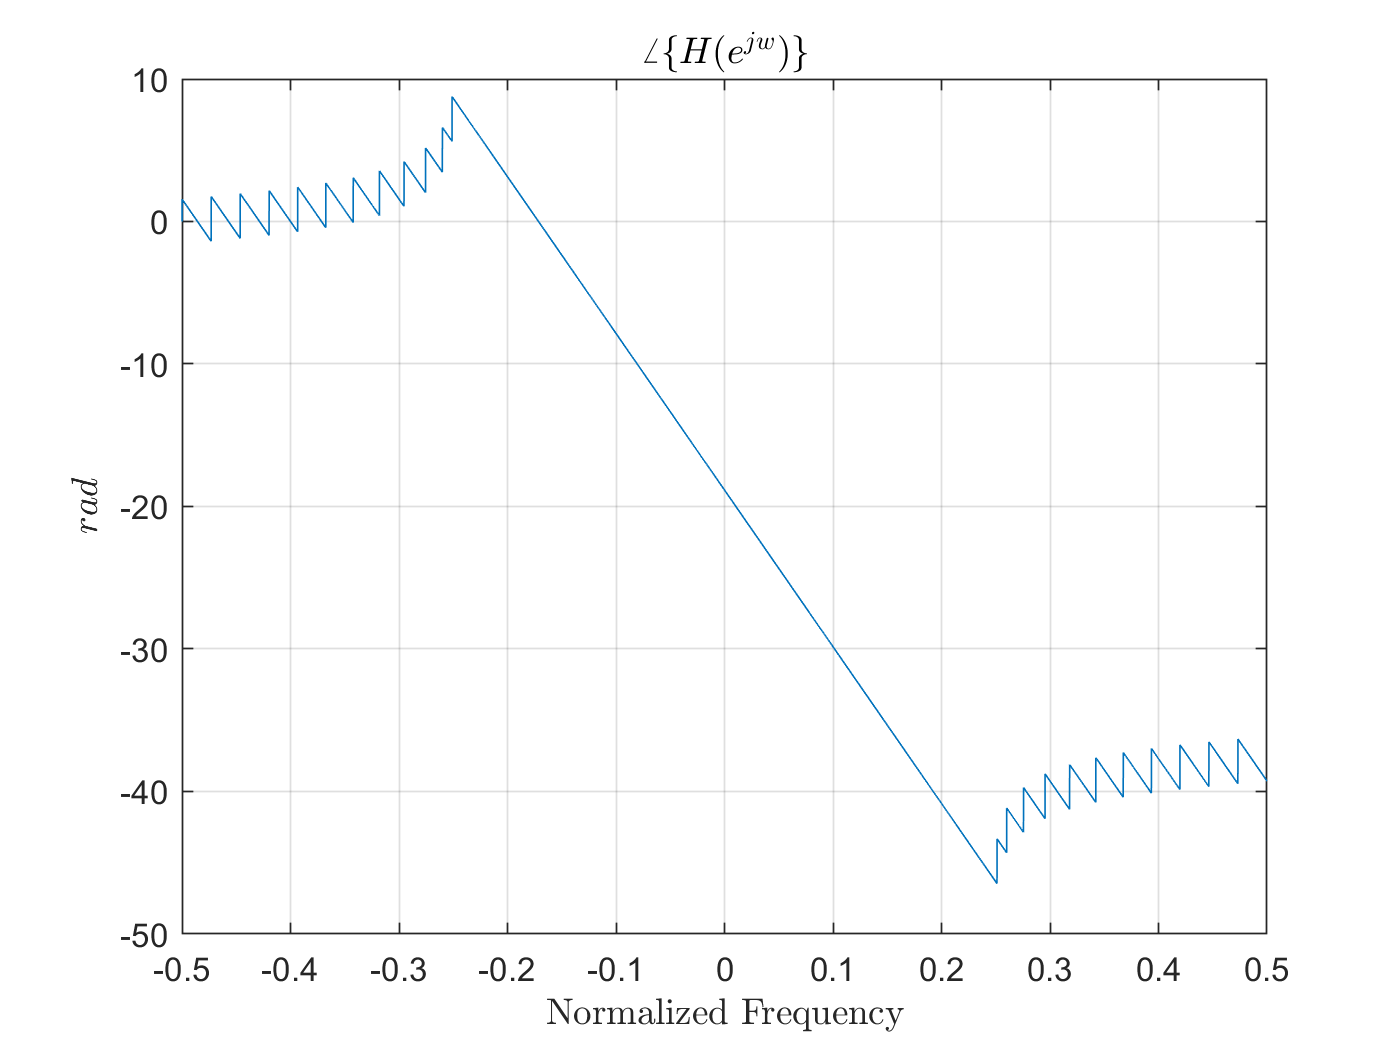


% Visualización gráfica de la respuesta en fase
f2 = figure;
a2 = axes;
plot(a2,linspace(-0.5,0.5,length(H)),unwrap(angle(H)))
xlabel(a2,'Normalized Frequency','Interpreter',"latex")
ylabel(a2,'$rad$','Interpreter',"latex")
title(a2,'$\angle\{H(e^{jw})\}$',"Interpreter",'latex')
grid(a2,'on')